5.6 오차막대를 가진 그래프

데이터에 포함된 불확실성, 즉 오차를 그래프에 표시하기 위해 오차막대(error bar)를이용할 수 있다. 오차막대는데이터 점이 나타내는 값과 관련된 오차의 크기를 데이터 점에 짧은 수직선으로 나타낸 것이다.

errorbar(x, y, e) : 그래프의 각 데이터 점에서 [y(i)-e(i)  y(i)+e(i)]의 오차막대를가지므로 오차막대는데이터 점에 대해 대칭이다.

또는

errorbar(x, y, L, U) : 각 데이터 점에서 [y(i)-L(i)  y(i)+U(i)] 길이의 오차 막대를 가지므로 오차막대는각 데이터 점에 대해 비대칭이다. 네 벡터의 length는 모두 동일해야 한다.

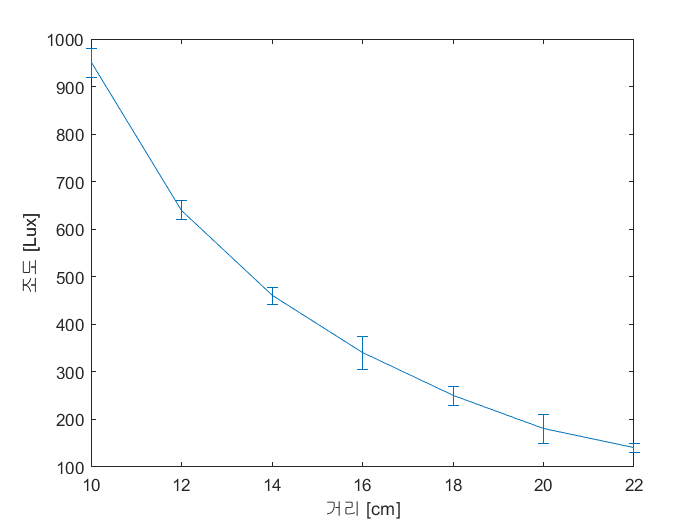

xd=[10:2:22];
yd=[950 640 460 340 250 180 140];
ydErr=[30 20 18 35 20 30 10];
errorbar(xd,yd,ydErr)
xlabel('거리 [cm]')
ylabel('조도 [Lux]')

5.7 특수 그래프

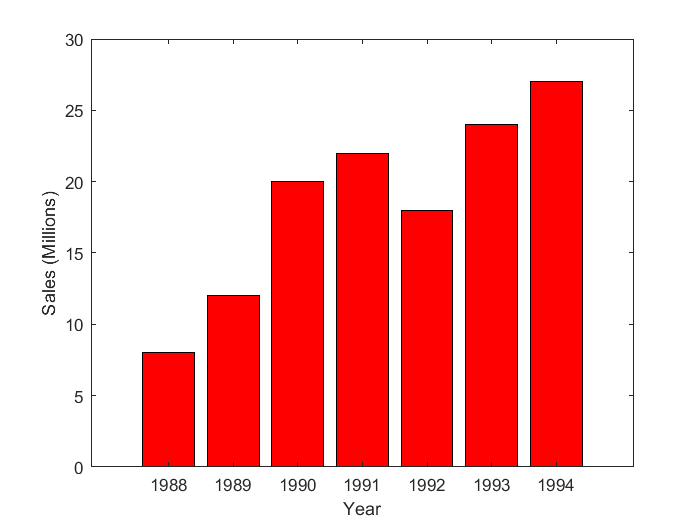

x=[1988:1994];  
y=[8 12 20 22 18 24 27];
bar(x, y, 'r') % x 위치에 y 크기
xlabel('Year')
ylabel('Sales (Millions)')

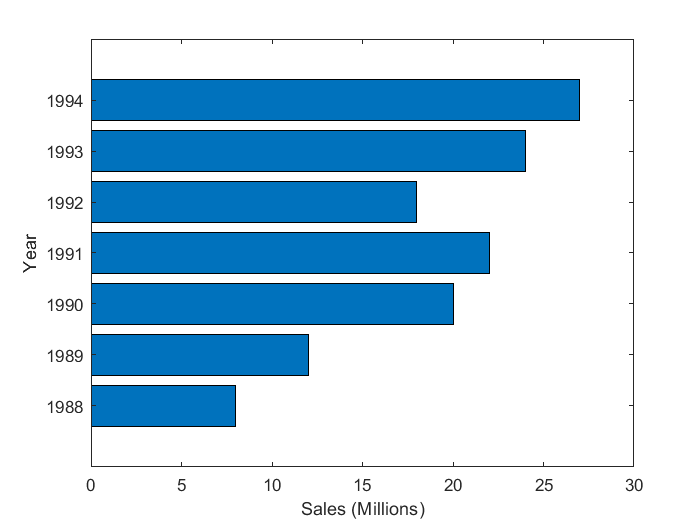

x=[1988:1994];
y=[8 12 20 22 18 24 27];
barh(x, y)  % x 위치에 y 크기
xlabel('Sales (Millions)')
ylabel('Year')

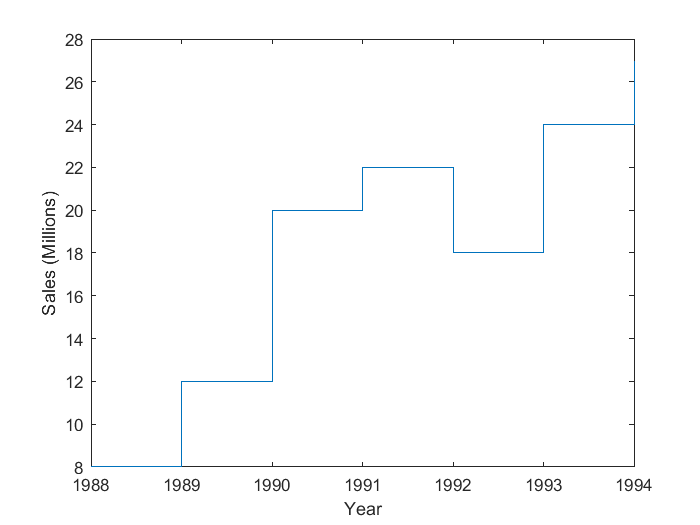

x=[1988:1994];
y=[8 12 20 22 18 24 27];
stairs(x, y)
xlabel('Year')
ylabel('Sales (Millions)')

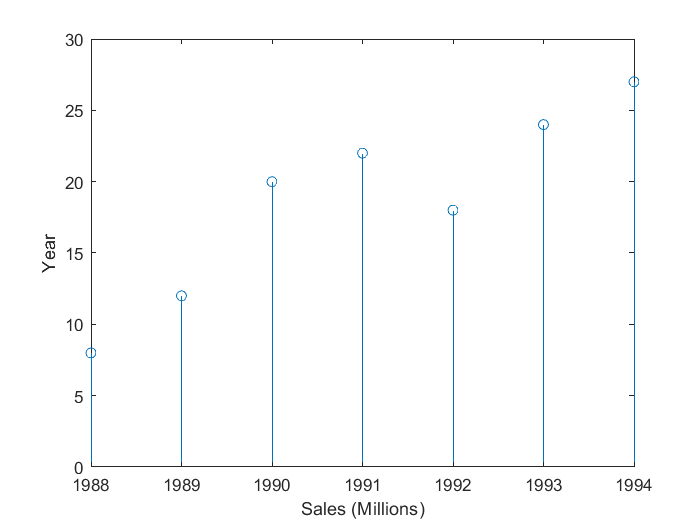

x=[1988:1994];
y=[8 12 20 22 18 24 27];
stem(x, y)
xlabel('Sales (Millions)')
ylabel('Year')

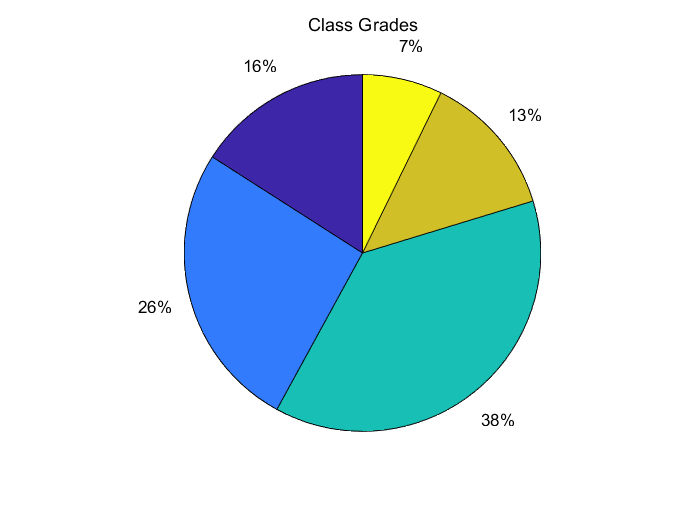

grd=[11 18 26 9 5];
pie(grd)
title('Class Grades')

5.8 히스토그램

히스토그램은 주어진 데이터의 전체 범위를 작은 구간(계급)들로 나누고 각 구간에 속하는 데이터의 개수(빈도수)를세로막대로나타내어 데이터의 크기별 분포를 보여준다. 

hist( y ) : y는 데이터 값 벡터. MATLAB이 y의 데이터 값 범위를  10 개의 등간격 구간으로 나눈 뒤, 각 구간의 빈도수를 막대그래프로 표시한다.

hist( y, nbins ) : nbins(스칼라)로 구간의 수를 지정할 수 있다. MATLAB이 nbins개의 등간격 구간을 만든다.

hist( y, x ) : x는 각 구간의 중앙 값들을 원소로 갖는 벡터이다. 각 구간의 경계는 두 중앙 값 사이의 중간 값이다.

[n, x]=hist( y ) : n은 각 구간의 빈도수(데이터 개수) 벡터, x는 구간의 중앙 값을 갖는 벡터이다.

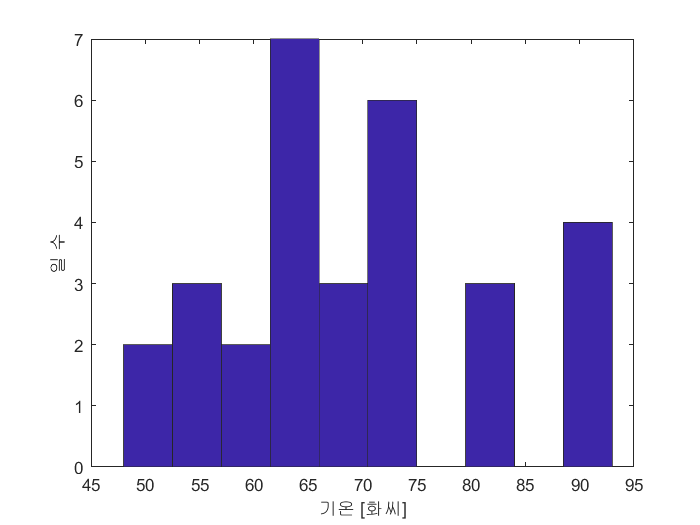

y=[58 73 73 53 50 48 56 73 73 66 69 63 74 82 84 91 93 89 ...
91 80 59 69 56 64 63 66 64 74 63 69];
hist(y);
xlabel('기온 [화씨]');
ylabel('일 수')

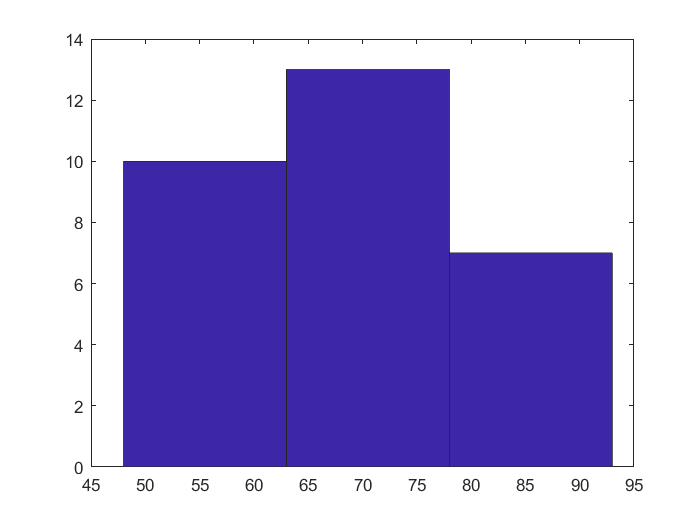

hist(y, 3);

x = [45:10:95]

x =     45    55    65    75    85    95


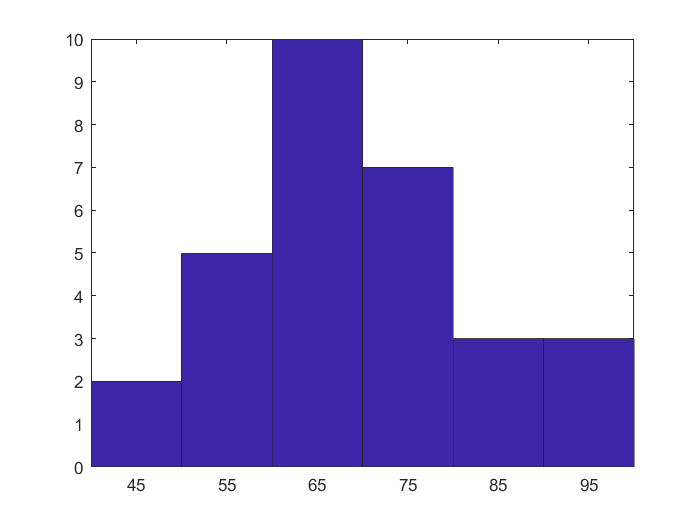

hist(y,x);

n1=hist(y);
n1

n1 =      2     3     2     7     3     6     0     3     0     4


n2=hist(y,x);
n2

n2 =      2     5    10     7     3     3


[n3 xout]=hist(y);
n3

n3 =      2     3     2     7     3     6     0     3     0     4


xout

xout =    50.2500   54.7500   59.2500   63.7500   68.2500   72.7500   77.2500   81.7500   86.2500   90.7500


5.10 동일 페이지에 다중 그래프 출력

subplot 명령어를 이용하여 동일한 페이지에 여러 개의 그래프를 그릴 수 있다.

subplot(m,  n,  p) : 그림 창을 m×n의 작은 사각형 그래프 영역으로 나누고, 왼쪽에서 오른쪽 순서대로 차례로 일련번호를 부여한 후, p 번째 영역을 그래프 출력 대상 영역으로 만든다. 

아래 예는 worspace에서 수행하기.

x = -4:0.1:4; 
n=length(x);
y=randn(10000, 1);
subplot(2,1,1);
hist(y,x);
x = 0:0.01:1; 
length(x)

ans = 101

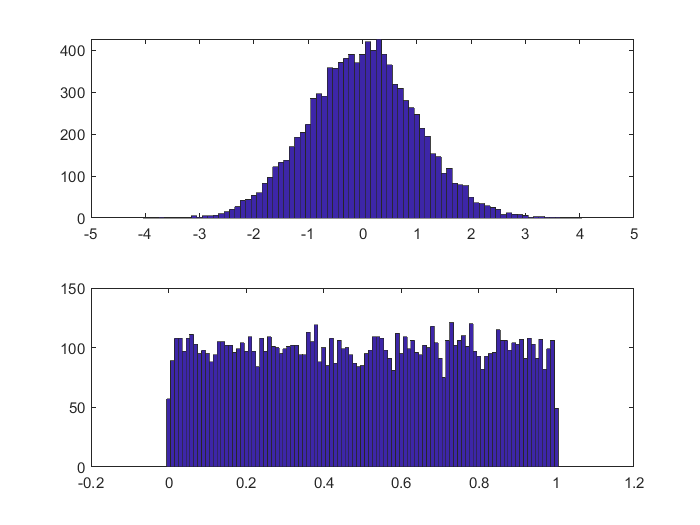

y=rand(10000,1); 
subplot(2,1,2);
hist(y,x);

x = -4:0.1:4; 
n=length(x);
y=randn(10000, 1);
subplot(1,2,1);
hist(y,x);
x = 0:0.01:1; 
length(x)

ans = 101

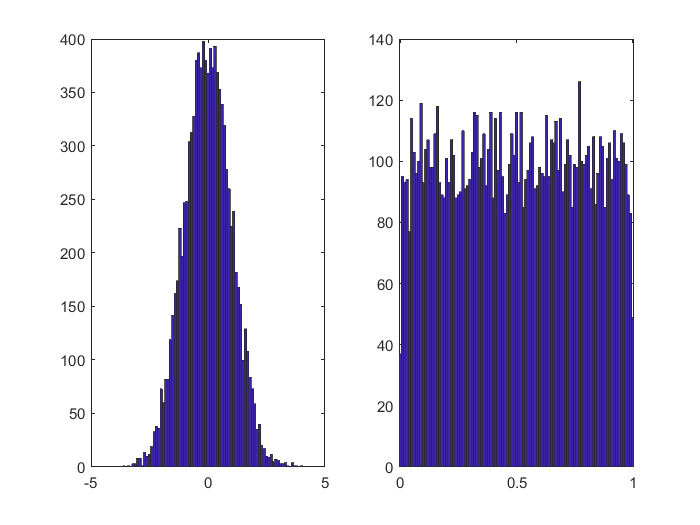

y=rand(10000,1); 
subplot(1,2,2);
hist(y,x);

figure 명령어가 입력될 때마다  새 그림 창이 만들어진다.

그림 창 제목은 생성 순서에 따라 Figure 1, Figure 2, … 등이 된다. 

아래 예는 worspace에서 수행하기.

x = -4:0.1:4; 
n=length(x);
y=randn(10000, 1);
figure;
hist(y,x);
x = 0:0.01:1; 
length(x)
y=rand(10000,1); 
figure;
hist(y,x);

figure;

figure;

x = -4:0.1:4; 
n=length(x);
y=randn(10000, 1);
figure(2);
hist(y,x);
x = 0:0.01:1; 
length(x)
y=rand(10000,1); 
figure(1);
hist(y,x);

그림 창은 close 명령어로 닫을 수 있다. 

close  현재 그림 창을 닫는다.

close(n)  n번째 그림 창을 닫는다.

close all  열린 모든그림 창을 닫는다.